Figures

Dependecies: 

- pangyuteng (2021). Convert Voronoi cells to region mask (https://www.mathworks.com/matlabcentral/fileexchange/43032-convert-voronoi-cells-to-region-mask), MATLAB Central File Exchange. Retrieved April 14, 2021.

% select which plots to run

saveflag = true; 
newpath = "";
path = path;

Select which plots to generate:

runDot =  true;
plotcolor = '#666666';
runVorAngle =  true;
runVorOrder =  true;
showColorbar = false;

If generating a local order plot, select a value to calculate the search radius:

r = 3;

 

% % Input: 
% if any plots are selected, ask user to select input file. If not throw error.
if (runDot | runVorAngle | runVorOrder) == false
    error("Please select a plot to run.")
end

if (runVorAngle | runVorOrder) == true
    % Load data from fiji output
    cd(userpath)
    [datafile, path] = uigetfile('*.csv');
    addpath(path);
    fijidata = readtable([path datafile]);
    % Convert Fiji results to usable data matrix
    Data = zeros(size(fijidata,1), 4);
    Data(:,1) = fijidata.X;
    Data(:,2) = fijidata.Y;
    Data(:,3) = fijidata.Angle+180;
    Data(:,4) = fijidata.Length>0;
    % Extract key values
    Data = sortrows(Data);
    imsize = ceil(Data(size(Data,1), 1:2));      % size of original image [x y] stored as last value in follicleData
    Data = Data(1:size(Data)-1,:);               % remove size measurement from dataset
    % change angle value for downgrown follicles to -1 to aid visualization (for colormap)
    Data(Data(:,4)==0,3)= -1;
end

Dot plot (angle vs A-P position)

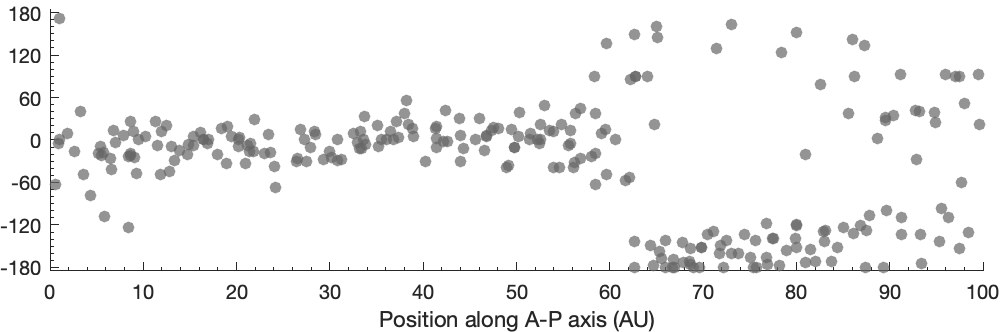

if runDot == true
    % plot of angle by A-P position (x-coord)
    AP = figure;
    angle180 = mod(Data(Data(:,4)==1,3)+180, 360)-180;
    scatter(Data(Data(:,4)==1,1)/imsize(1)*100, angle180,'MarkerFaceColor',plotcolor, 'MarkerEdgeColor',"none", 'MarkerFaceAlpha', .7);
    xlabel('Position along A-P axis (AU)');
    % ylabel('Follicle angle (degrees)');
    yticks(-180:60:180);
    ax = gca;
    ax.YLim = [-185 185];
    ax.XLim = [0 100];
    ax.XMinorTick = true;
    ax.YMinorTick = true;
    AP.Position(3:4) = [imsize(1)/imsize(1)*500, imsize(2)/imsize(1)*500];
    outerpos = ax.OuterPosition;
    ti = ax.TightInset; 
    left = outerpos(1) + ti(1);
    bottom = outerpos(2) + ti(2);
    ax_width = outerpos(3) - ti(1) - ti(3);
    ax_height = outerpos(4) - ti(2) - ti(4);
    ax.Position = [left bottom ax_width ax_height];
    ax.Color = 'none';
    if saveflag == true
        exportgraphics(AP,[path, extractBefore(datafile, '.csv'), ' Dot plot', '.eps'],'BackgroundColor','none','ContentType','vector');
    end 
end

clf('reset')

if (runVorAngle | runVorOrder) == true
    % create a mask based on voronoi diagrams, using centroids in grown as the seed points
    mask = voronoi2mask(Data(:,1),Data(:,2),[imsize(2), imsize(1)]);
    mask = imerode(mask, [strel('line', 3, 0), strel('line', 3, 90)]);
end

Voronoi angle diagram

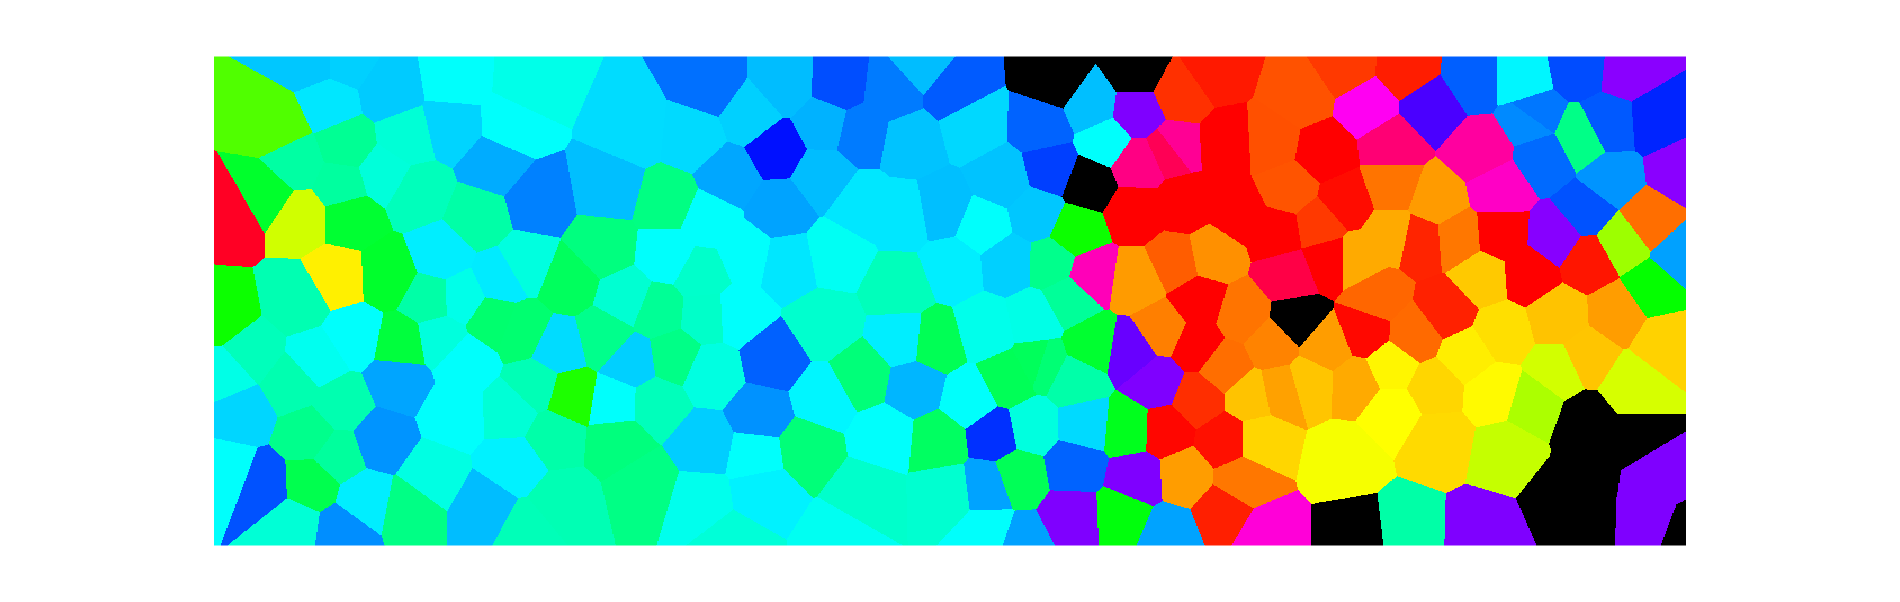

if runVorAngle == true
    % define 0:360 angle colormap
    n = 720;        % two colors defined per angle for an even distribution
    % offsets the hsv colormap to center 0° at cyan
    cmap = hsv2rgb(horzcat([(round(n/2):n)./n (0:round(n/2)-1)./n]', repelem(1, n+1)', repelem(1, n+1)'));  % 0° = cyan
    % adds zeros to correspond to negative numbers (ie NaNs, to color black)
    cmap = vertcat([0 0 0; 0 0 0], cmap);
    % creates a masked image with voronoi cells color-coded by angle
    maskcmap = voronoiangle(mask, Data);
    
    % display voronoi diagram colored by angle
    anglemap = figure;
    imshow(maskcmap);           
    colormap(cmap);
    caxis([-1 360])
    if showColorbar == true
        colorbar
        colorbar('Ticks', [0,90,180,270,360]);
    end 
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
    if saveflag == true
        exportgraphics(anglemap,[path, datafile, ' Angle Map', '.eps'],'BackgroundColor','none','ContentType','vector');
    end
end

Voronoi order diagram

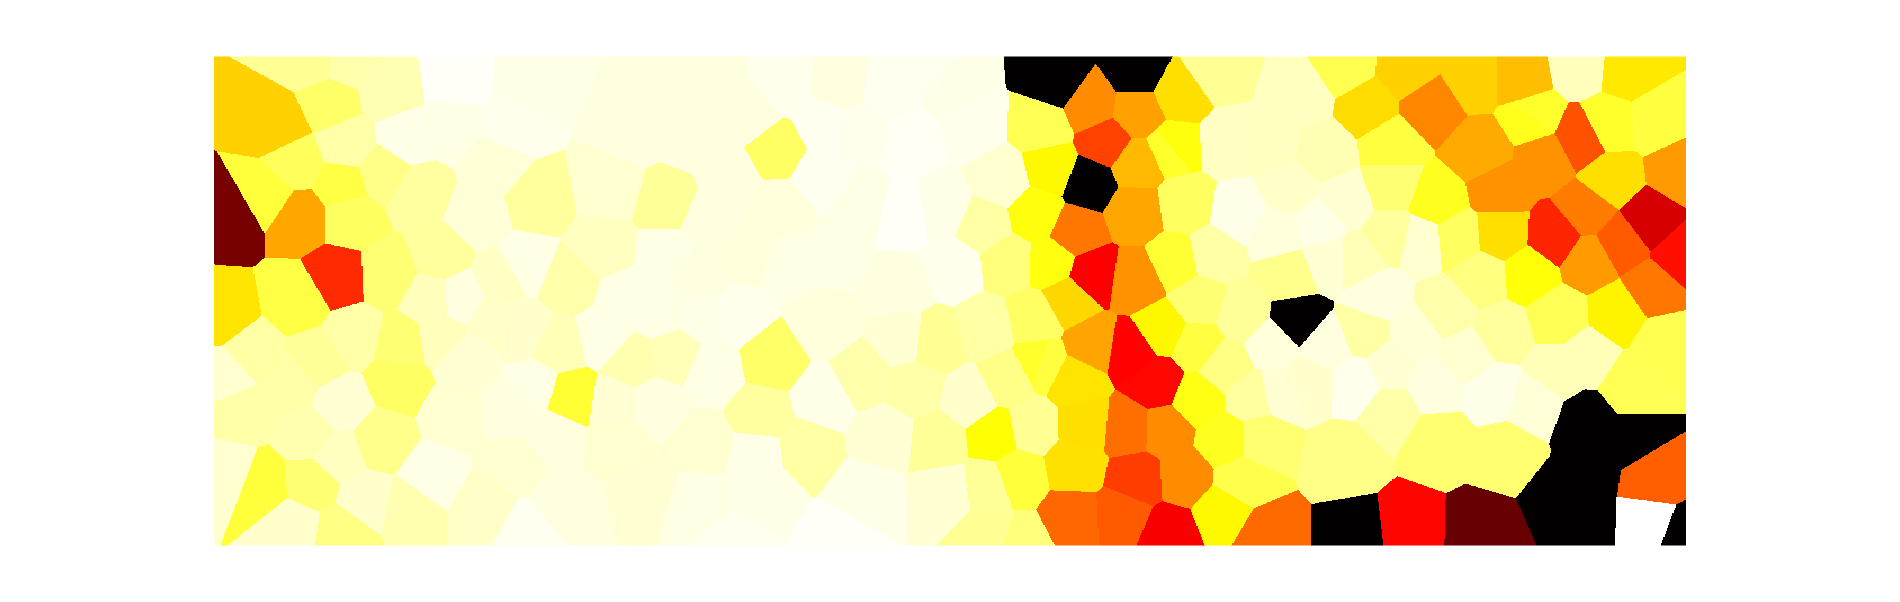

if runVorOrder == true
    numneighbors = 1;
    % creates a masked image with voronoi cells color-coded by local order
    % numneighbors is used to calculate ave. distance to the nearest 'numneighbors' neighbors
    % r is the multiple used to calculate the search radius using this
    % average distance. Set both above.
    % search radius = r * ave. distance
    [omaskcmap, avedist, Idx] = voronoiorder(mask, Data, numneighbors, r);
    % display
    ordermap = figure;
    imshow(omaskcmap);
    colormap(hot)
    if showColorbar == true
        colorbar('Ticks', [0, 1], 'TickLabels', [{'low order'}, {'high order'}])
    end
    truesize(gcf, [imsize(2)/6 imsize(1)/6])      % display at 1/6 resolution because it fits on screen
    if saveflag == true
        exportgraphics(ordermap,[path, datafile, ' Order Map', '.eps'],'BackgroundColor','none','ContentType','vector');
    end
end

function [maskcmap] = voronoiangle(mask, Data)
maskcmap = mask;
% create heatmap by angle
for i = 1:size(Data, 1)
    maskcmap(maskcmap==i) = Data(i, 3);
end
end


function [omaskcmap, avedist, Idx] = voronoiorder(mask, Data, numneighbors, r)
% Order parameter calculation: uses matrix w downgrown points, but excludes
% from analysis
[~, dist] = knnsearch(Data(:,1:2), ...
    Data(:,1:2), 'K', numneighbors+1);                 % find distances to nearest neighbor(s)
avedist = mean(dist(:,2:numneighbors+1), 'all');        % average distance to n nearest neighbors
Idx = rangesearch(Data(Data(:,4)==1,1:2),Data(Data(:,4)==1,1:2),r*avedist);
% associate Idx index with 'Data    ' table index
k = 1;
for i = 1:(size(Data,1))
    if Data(i,4)==1
        Idx{k,2} = i;
        k = k+1;
    end
end
% calculate order parameter
order = zeros([size(Data,1),1], 'double');
for i = 1:size(Idx,1)
    ordertotal = 0;
    for j = 2:size(Idx{i,1},2)
        ordertotal = ordertotal + ...
            (cosd(Data(Idx{i,2},3) - Data(Idx{Idx{i,1}(j), 2},3))+1)./2;
    end
    order(Idx{i,2}, 1) = ordertotal./(size(Idx{i,1},2)-1);
end
% convert labels in mask to the order value
omaskcmap = mask;
for i = 1:size(Data, 1)
    omaskcmap(omaskcmap==i) = order(i, 1);
end
end